# Difference of Gaussians

## How it works

A gaussian blur is applied to an image two times and the difference of them is taken. The result is an image with its edges highlighted.

### 
$$G_{\sigma } -G_{k\sigma }$$


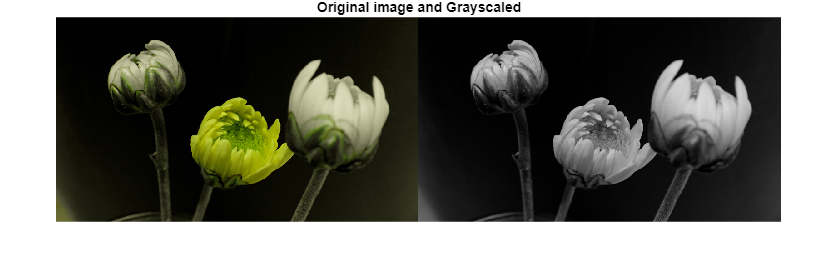

buds = imread("assets\blooming_buds.jpg");

% convert to grayscale image between [0 1]
gray_buds = double(rgb2gray(buds))/255.0;
montage({buds, gray_buds});
title("Original image and Grayscaled");

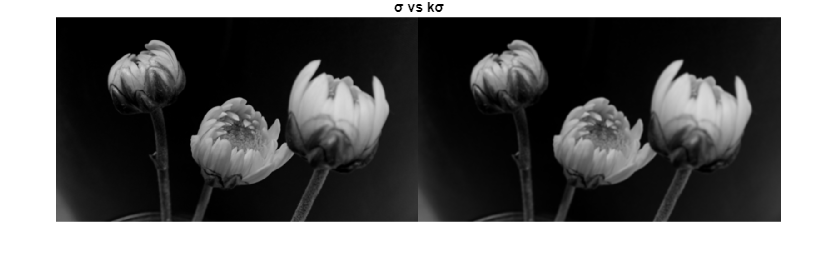

sigma =5; % σ
k = 1.6;
G_sig = imgaussfilt(gray_buds, sigma);
G_k_sig = imgaussfilt(gray_buds, sigma*k);
DoG = G_sig - G_k_sig;
montage({G_sig, G_k_sig});
title("σ vs kσ");

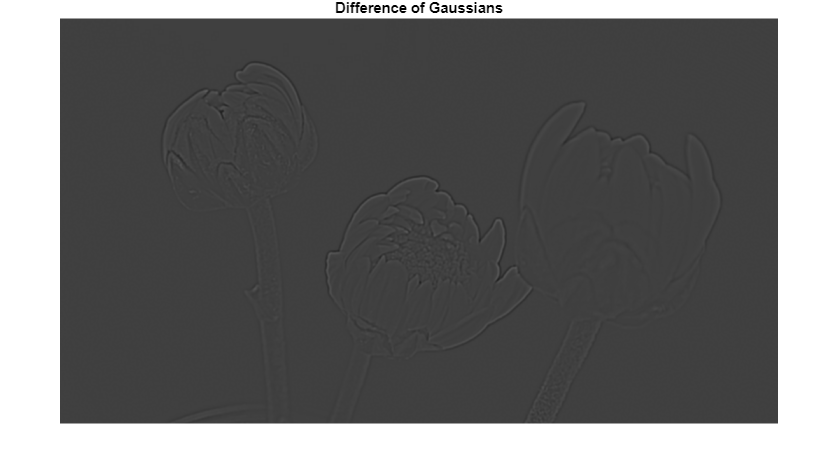

% the DoG exposure is increased by 0.25 to better see the result
imshow(DoG + 0.25);
title("Difference of Gaussians");

We can apply a threshold which results in a binary image.

### 
$$T_{\varepsilon } \left(u\right)=\left\lbrace \begin{array}{ll}
1 & u\ge \varepsilon \\
0 & \mathrm{otherwise}
\end{array}\right.$$


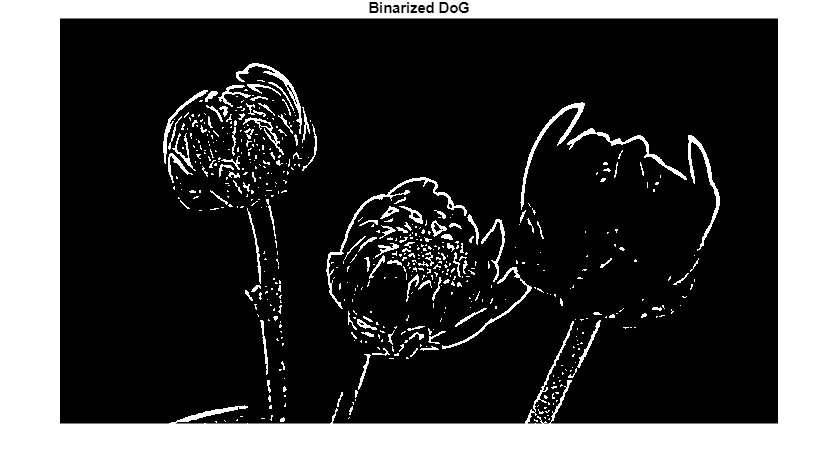

% Threshold
thresh =0.00875; % ε
Bin_DoG = DoG;
Bin_DoG(Bin_DoG >= thresh) = 1;
Bin_DoG(Bin_DoG < thresh) = 0;

imshow(Bin_DoG);
title("Binarized DoG");

# XDoG: An eXtended Difference-of-Gaussians used for advanced image styization

We continue from the Difference of Gaussians and try to generalize and extend it in an aesthetic way. We try to derive some styles such as pencil-shading, pastel, hatching and woodcut as well as a range of subtle artistic effects.